%%% using geoplot 

figure;
geoplot(y,x)
geolimits([66.6 83.9],[-30.7 68.2])
hold on 
a = linspace(0, 2*pi, 100);
r = 4

r = 4

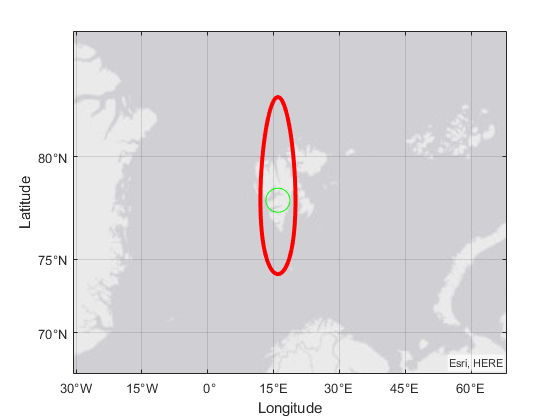

xunits = r*cos(a) + fpi_loc(2);
yunits = r*sin(a) + fpi_loc(1);
geoplot(yunits, xunits, 'Color', 'r', 'LineWidth', 3);
hold on
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"));
geoplot(lat,lon,"g")

figure;
gx = geoaxes;
a = linspace(0, 2*pi, 100);
r = 4

r = 4

%xunits = r*cos(a) + fpi_loc(2);
%yunits = r*sin(a) + fpi_loc(1);
a = linspace(0, 2*pi, 6*10);
x = 0

x = 0

y = 0

y = 0

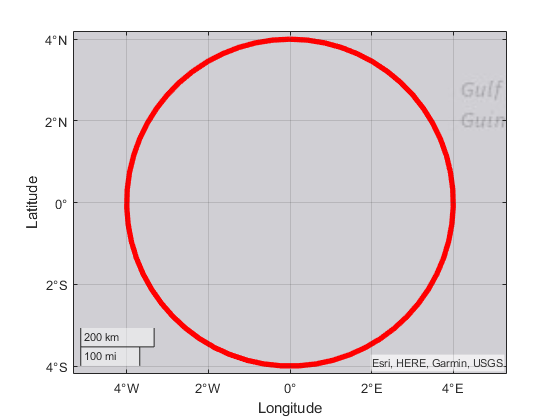

xunits = r*cos(a) + x;
yunits = r*sin(a) + y;
geoplot(xunits, yunits, 'Color', 'r', 'LineWidth', 4);

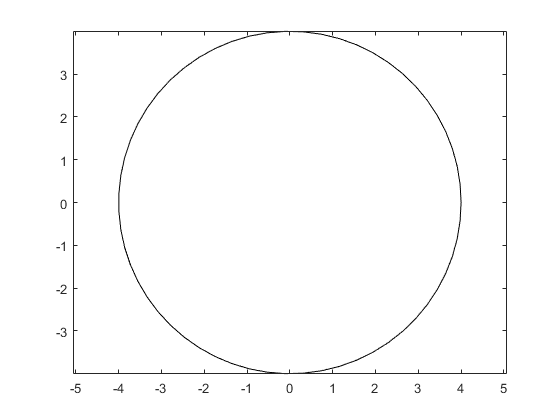

fill(xunits,yunits, "w");
hold on
%geoplot([zeros(1,6); xunits(1:10:end)], [zeros(1,6); yunits(1:10:end)],'color', 'r');
axis equal
%geoplot(gx,yunits,xunits)
hold on

quiverm(0,0,5,5)

Error using gcm (line 25)
Not a map axes.

Error in quiverm (line 88)
    mstruct = gcm;

hold off


figure;
load coastlines.mat;
[X,Y]= meshgrid(-179:180, -89:90);
plot(coastlon, coastlat,"r","LineWidth",2, "Color","g")
hold on 
xlim([-12.2 47.3])
ylim([61.1 90.8])
a = linspace(0, 2*pi, 6*10);
x = fpi_loc(2)

x = 16

y = fpi_loc(1)

y = 78.1000

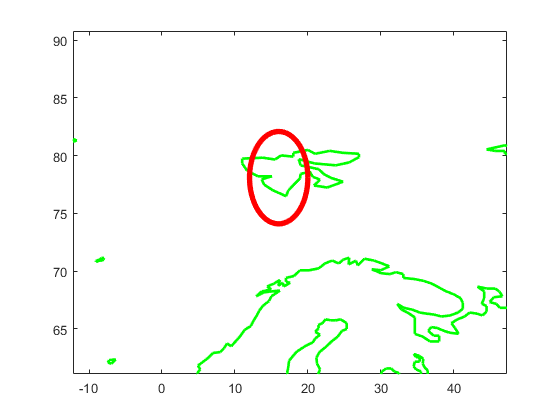

xunits = r*cos(a) + x;
yunits = r*sin(a) + y;
plot(xunits, yunits, 'Color', 'r', 'LineWidth', 4);
hold off

%%% using geoplot 

figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


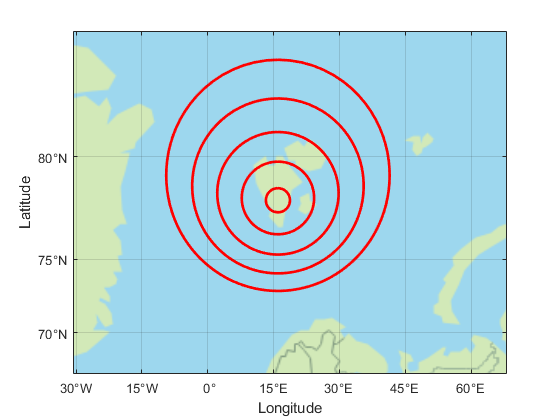

geolimits([66.6 83.9],[-30.7 68.2])
hold on
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
[lat,lon] = scircle1(78.1,16,188.46,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
[lat,lon] = scircle1(78.1,16,314.11,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
[lat,lon] = scircle1(78.1,16,439.75,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
[lat,lon] = scircle1(78.1,16,565.40,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)

geoshape(71,15,"Color","black","LineWidth", 20)

ans =  1×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
     Latitude: 71
    Longitude: 15
 Feature properties:
        Color: 'black'
    LineWidth: 20


%%% more efficient code than the previous 
figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


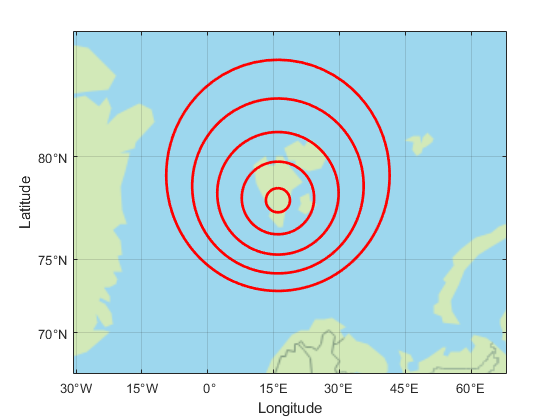

geolimits([66.6 83.9],[-30.7 68.2])
hold on
[lat,lon] = scircle1(78.1,16,r,[],earthRadius("km"));
for i=[1:5]
    geoplot(lat(:,i),lon(:,i),"r","LineWidth", 2)
end

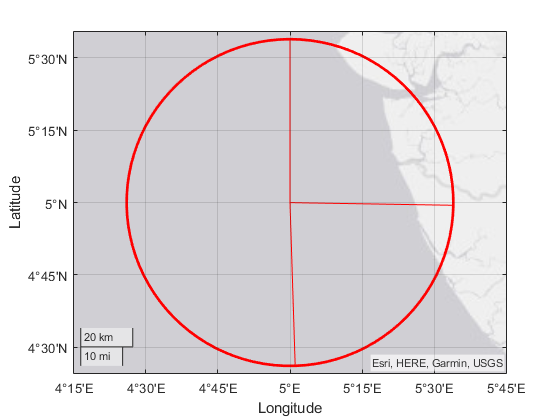

figure;
[lat,lon] = scircle1(5,5,62.8,360,earthRadius('km'));
geoplot(lat(:,1), lon(:,1),"r","LineWidth", 2)
hold on
geoplot([lat(1), 5, lat(26), 5, lat(50)], [lon(1),5,lon(26),5, lon(50)], 'r')
hold off

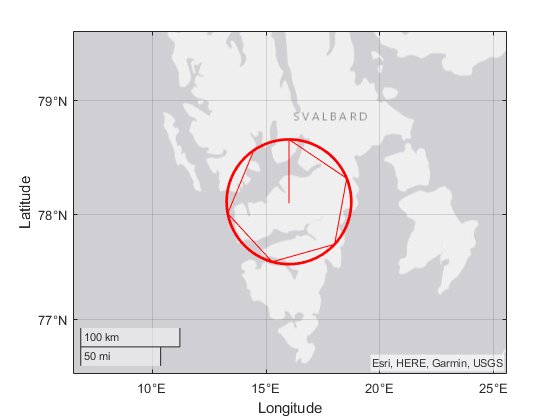

figure;
[lat,lon] = scircle1(78.1,16,62.8,360,earthRadius('km'));
geoplot(lat(:,1), lon(:,1),"r","LineWidth", 2)
hold on
geoplot([repmat(y,N,1); (lat(1:18:end))], [repmat(x,N,1); (lon(1:18:end))],'color', 'r');
hold off

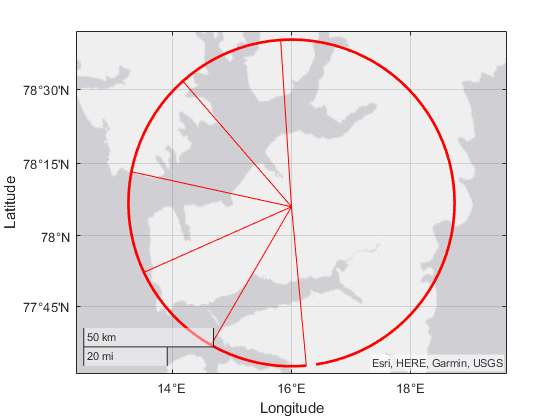

figure;
geoplot(lat(:,1), lon(:,1),"r","LineWidth", 2)
hold on
geoplot(outy, outx,'color', 'r');
hold off

figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


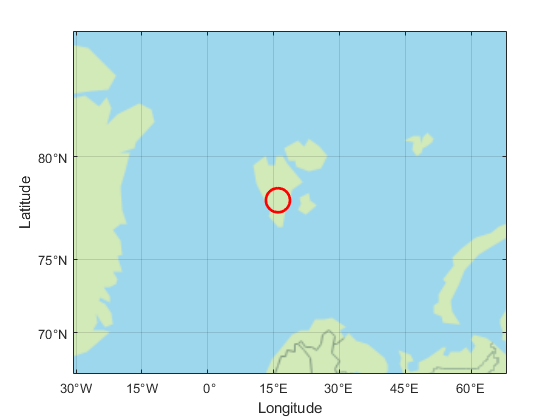

geolimits([66.6 83.9],[-30.7 68.2])
hold on
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"),"degrees",60);
geoplot(lat,lon,"r","LineWidth", 2)
hold off

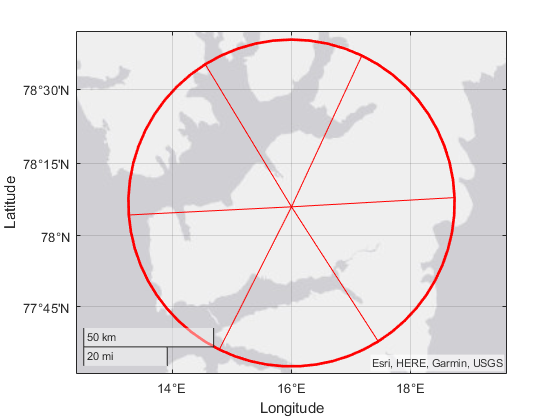

figure;
geoplot(lat(:,1), lon(:,1),"r","LineWidth", 2)
hold on
geoplot(outy, outx,'color', 'r');
hold off

figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


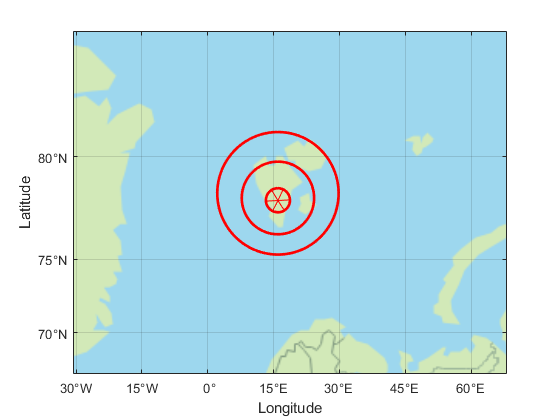

geolimits([66.6 83.9],[-30.7 68.2])
hold on
[lat,lon] = scircle1(78.1,16,314.11,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
[lat,lon] = scircle1(78.1,16,188.46,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold on
geoplot(outy, outx,'color', 'r');
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)
hold off

figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


geolimits([66.6 83.9],[-30.7 68.2])

hold on
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"));
geoplot(lat,lon,"r","LineWidth", 2)

hold on
N=6

N = 6

[lat,lon] = scircle1(78.1,16,188.46,[],earthRadius("km"),"degrees",N*10)

lat =    79.7949
   79.7837
   79.7504
   79.6955
   79.6201
   79.5253
   79.4128
   79.2844
   79.1420
   78.9878


lon =    16.0000
   17.0156
   18.0136
   18.9768
   19.8894
   20.7375
   21.5090
   22.1942
   22.7859
   23.2791


[outy,outx] = circle_sectors(lat,lon,N)

lat1 =    77.9370
   78.1163
   78.2966
   78.4761
   78.6526
   78.8239
   78.9878
   79.1420
   79.2844
   79.4128


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    77.9370   79.5253   79.6201   78.1163   76.6552   76.5736


outy =    77.9370   78.1000   79.5253   78.1000   79.6201   78.1000   78.1163   78.1000   76.6552   78.1000   76.5736   78.1000


t2 =     16    16    16    16    16    16


tx =     7.8669   11.2625   19.8894   24.2313   20.0621   12.6329


outx =     7.8669   16.0000   11.2625   16.0000   19.8894   16.0000   24.2313   16.0000   20.0621   16.0000   12.6329   16.0000


outy =    77.9370   78.1000   79.5253   78.1000   79.6201   78.1000   78.1163   78.1000   76.6552   78.1000   76.5736   78.1000


outx =     7.8669   16.0000   11.2625   16.0000   19.8894   16.0000   24.2313   16.0000   20.0621   16.0000   12.6329   16.0000


geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');

hold on
N=18

N = 18

[lat,lon] = scircle1(78.1,16,314.11,[],earthRadius("km"),"degrees",N*10)

lat =    80.9249
   80.9226
   80.9158
   80.9044
   80.8886
   80.8683
   80.8437
   80.8146
   80.7814
   80.7440


lon =    16.0000
   16.6281
   17.2546
   17.8779
   18.4962
   19.1082
   19.7123
   20.3069
   20.8907
   21.4625


[outy,outx] = circle_sectors(lat,lon,N)

lat1 =    75.5684
   75.6096
   75.6535
   75.6999
   75.7489
   75.8003
   75.8542
   75.9105
   75.9692
   76.0303


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    75.5684   76.0936   76.8410   77.7499   78.7339   79.6773   80.4378   80.8683   80.8886   80.4980   79.7641   78.8322   77.8466   76.9258   76.1591   75.6096   75.3178   75.3037


outy =    75.5684   78.1000   76.0936   78.1000   76.8410   78.1000   77.7499   78.1000   78.7339   78.1000   79.6773   78.1000   80.4378   78.1000   80.8683   78.1000   80.8886   78.1000   80.4980   78.1000   79.7641   78.1000   78.8322   78.1000   77.8466   78.1000   76.9258   78.1000   76.1591   78.1000   75.6096   78.1000   75.3178   78.1000   75.3037   78.1000


t2 =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


tx =    10.4705    7.0600    4.3097    2.5697    2.2532    3.7871    7.4259   12.8918   18.4962   24.0984   27.9447   29.6831   29.5333   27.9161   25.2500   21.8915   18.1380   14.2489


outx =    10.4705   16.0000    7.0600   16.0000    4.3097   16.0000    2.5697   16.0000    2.2532   16.0000    3.7871   16.0000    7.4259   16.0000   12.8918   16.0000   18.4962   16.0000   24.0984   16.0000   27.9447   16.0000   29.6831   16.0000   29.5333   16.0000   27.9161   16.0000   25.2500   16.0000   21.8915   16.0000   18.1380   16.0000   14.2489   16.0000


outy =    75.5684   78.1000   76.0936   78.1000   76.8410   78.1000   77.7499   78.1000   78.7339   78.1000   79.6773   78.1000   80.4378   78.1000   80.8683   78.1000   80.8886   78.1000   80.4980   78.1000   79.7641   78.1000   78.8322   78.1000   77.8466   78.1000   76.9258   78.1000   76.1591   78.1000   75.6096   78.1000   75.3178   78.1000   75.3037   78.1000


outx =    10.4705   16.0000    7.0600   16.0000    4.3097   16.0000    2.5697   16.0000    2.2532   16.0000    3.7871   16.0000    7.4259   16.0000   12.8918   16.0000   18.4962   16.0000   24.0984   16.0000   27.9447   16.0000   29.6831   16.0000   29.5333   16.0000   27.9161   16.0000   25.2500   16.0000   21.8915   16.0000   18.1380   16.0000   14.2489   16.0000


geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');

hold on
N=18

N = 18

[lat,lon] = scircle1(78.1,16,439.76,[],earthRadius("km"),"degrees",N*10)

lat =    82.0549
   82.0512
   82.0403
   82.0223
   81.9971
   81.9648
   81.9256
   81.8797
   81.8272
   81.7683


lon =    16.0000
   17.0029
   18.0022
   18.9942
   19.9754
   20.9424
   21.8921
   22.8213
   23.7272
   24.6073


[outy,outx] = circle_sectors(lat,lon,N)

lat1 =    74.5277
   74.5817
   74.6391
   74.6999
   74.7640
   74.8315
   74.9022
   74.9762
   75.0534
   75.1337


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    74.5277   75.2171   76.2090   77.4361   78.7990   80.1528   81.2927   81.9648   81.9971   81.3853   80.2804   78.9377   77.5683   76.3224   75.3036   74.5817   74.2006   74.1823


outy =    74.5277   78.1000   75.2171   78.1000   76.2090   78.1000   77.4361   78.1000   78.7990   78.1000   80.1528   78.1000   81.2927   78.1000   81.9648   78.1000   81.9971   78.1000   81.3853   78.1000   80.2804   78.1000   78.9377   78.1000   77.5683   78.1000   76.3224   78.1000   75.3036   78.1000   74.5817   78.1000   74.2006   78.1000   74.1823   78.1000


t2 =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


tx =     8.7626    4.1794    0.2880   -2.4848   -3.5401   -2.0710    2.7648   11.0576   19.9754   28.5491   33.7504   35.5216   34.6793   32.0480   28.2469   23.7171   18.7858   13.7189


outx =     8.7626   16.0000    4.1794   16.0000    0.2880   16.0000   -2.4848   16.0000   -3.5401   16.0000   -2.0710   16.0000    2.7648   16.0000   11.0576   16.0000   19.9754   16.0000   28.5491   16.0000   33.7504   16.0000   35.5216   16.0000   34.6793   16.0000   32.0480   16.0000   28.2469   16.0000   23.7171   16.0000   18.7858   16.0000   13.7189   16.0000


outy =    74.5277   78.1000   75.2171   78.1000   76.2090   78.1000   77.4361   78.1000   78.7990   78.1000   80.1528   78.1000   81.2927   78.1000   81.9648   78.1000   81.9971   78.1000   81.3853   78.1000   80.2804   78.1000   78.9377   78.1000   77.5683   78.1000   76.3224   78.1000   75.3036   78.1000   74.5817   78.1000   74.2006   78.1000   74.1823   78.1000


outx =     8.7626   16.0000    4.1794   16.0000    0.2880   16.0000   -2.4848   16.0000   -3.5401   16.0000   -2.0710   16.0000    2.7648   16.0000   11.0576   16.0000   19.9754   16.0000   28.5491   16.0000   33.7504   16.0000   35.5216   16.0000   34.6793   16.0000   32.0480   16.0000   28.2469   16.0000   23.7171   16.0000   18.7858   16.0000   13.7189   16.0000


geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');

hold on
N=18

N = 18

[lat,lon] = scircle1(78.1,16,565.40,[],earthRadius("km"),"degrees",N*10)

lat =    83.1848
   83.1793
   83.1631
   83.1361
   83.0985
   83.0505
   82.9925
   82.9247
   82.8474
   82.7612


lon =    16.0000
   17.5008
   18.9936
   20.4707
   21.9246
   23.3484
   24.7355
   26.0802
   27.3774
   28.6227


[outy,outx] = circle_sectors(lat,lon,N)

lat1 =    73.4757
   73.5407
   73.6100
   73.6833
   73.7607
   73.8422
   73.9278
   74.0172
   74.1106
   74.2079


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    73.4757   74.3090   75.5174   77.0326   78.7518   80.5180   82.0789   83.0505   83.0985   82.2099   80.6885   78.9296   77.1974   75.6565   74.4139   73.5407   73.0820   73.0599


outy =    73.4757   78.1000   74.3090   78.1000   75.5174   78.1000   77.0326   78.1000   78.7518   78.1000   80.5180   78.1000   82.0789   78.1000   83.0505   78.1000   83.0985   78.1000   82.2099   78.1000   80.6885   78.1000   78.9296   78.1000   77.1974   78.1000   75.6565   78.1000   74.4139   78.1000   73.5407   78.1000   73.0820   78.1000   73.0599   78.1000


t2 =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


tx =     7.2663    1.6200   -3.3723   -7.2630   -9.3421   -8.4446   -2.8561    8.6516   21.9246   33.9720   40.1283   41.4106   39.5674   35.8200   30.9147   25.3183   19.3499   13.2575


outx =     7.2663   16.0000    1.6200   16.0000   -3.3723   16.0000   -7.2630   16.0000   -9.3421   16.0000   -8.4446   16.0000   -2.8561   16.0000    8.6516   16.0000   21.9246   16.0000   33.9720   16.0000   40.1283   16.0000   41.4106   16.0000   39.5674   16.0000   35.8200   16.0000   30.9147   16.0000   25.3183   16.0000   19.3499   16.0000   13.2575   16.0000


outy =    73.4757   78.1000   74.3090   78.1000   75.5174   78.1000   77.0326   78.1000   78.7518   78.1000   80.5180   78.1000   82.0789   78.1000   83.0505   78.1000   83.0985   78.1000   82.2099   78.1000   80.6885   78.1000   78.9296   78.1000   77.1974   78.1000   75.6565   78.1000   74.4139   78.1000   73.5407   78.1000   73.0820   78.1000   73.0599   78.1000


outx =     7.2663   16.0000    1.6200   16.0000   -3.3723   16.0000   -7.2630   16.0000   -9.3421   16.0000   -8.4446   16.0000   -2.8561   16.0000    8.6516   16.0000   21.9246   16.0000   33.9720   16.0000   40.1283   16.0000   41.4106   16.0000   39.5674   16.0000   35.8200   16.0000   30.9147   16.0000   25.3183   16.0000   19.3499   16.0000   13.2575   16.0000


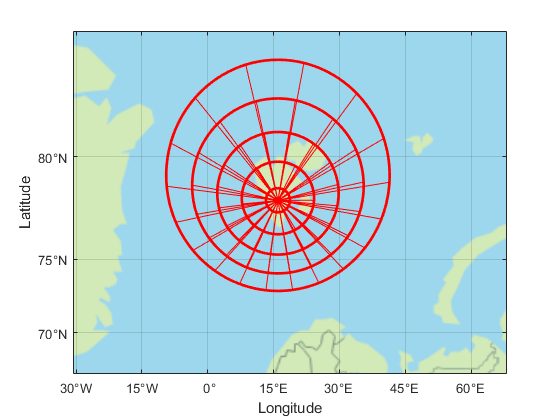

geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');

hold off

figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


geolimits([66.6 83.9],[-30.7 68.2])

hold on
N=6

N = 6

[lat,lon] = scircle1(78.1,16,188.46,[],earthRadius("km"),"degrees",N*10)

lat =    79.7949
   79.7837
   79.7504
   79.6955
   79.6201
   79.5253
   79.4128
   79.2844
   79.1420
   78.9878


lon =    16.0000
   17.0156
   18.0136
   18.9768
   19.8894
   20.7375
   21.5090
   22.1942
   22.7859
   23.2791


[outy,outx] = circle_sectors(lat,lon,N)

lat1 =    77.9370
   78.1163
   78.2966
   78.4761
   78.6526
   78.8239
   78.9878
   79.1420
   79.2844
   79.4128


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    77.9370   79.5253   79.6201   78.1163   76.6552   76.5736


outy =    77.9370   78.1000   79.5253   78.1000   79.6201   78.1000   78.1163   78.1000   76.6552   78.1000   76.5736   78.1000


t2 =     16    16    16    16    16    16


tx =     7.8669   11.2625   19.8894   24.2313   20.0621   12.6329


outx =     7.8669   16.0000   11.2625   16.0000   19.8894   16.0000   24.2313   16.0000   20.0621   16.0000   12.6329   16.0000


outy =    77.9370   78.1000   79.5253   78.1000   79.6201   78.1000   78.1163   78.1000   76.6552   78.1000   76.5736   78.1000


outx =     7.8669   16.0000   11.2625   16.0000   19.8894   16.0000   24.2313   16.0000   20.0621   16.0000   12.6329   16.0000


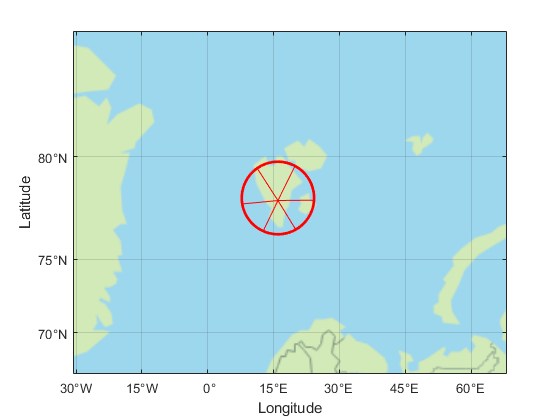

geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');
hold off